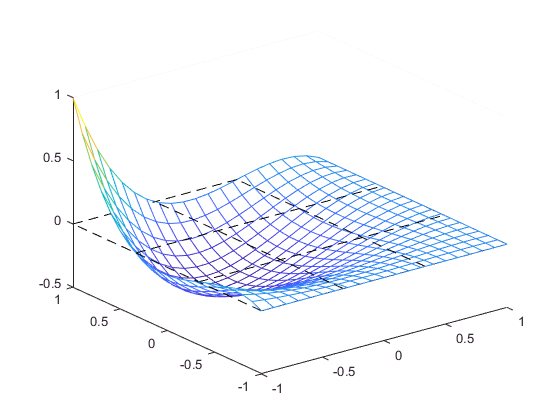

clc; clear; close all;

syms xi eta; % be careful performance issue.

nodes = linspace(-1, 1, 4);
linear_nodes = linspace(-1, 1, 2);

shape_xi_l1 = lagrange_interpolation(linear_nodes, 1, xi);
shape_eta_l2 = lagrange_interpolation(linear_nodes, 2, eta);
N_4 = shape_xi_l1 * shape_eta_l2;

shape_eta_3 = lagrange_interpolation(nodes, 3, eta);
N_11 = shape_xi_l1 * shape_eta_3;

shape_eta_2 = lagrange_interpolation(nodes, 2, eta);
N_12 = shape_xi_l1 * shape_eta_2;

shape_xi_2 = lagrange_interpolation(nodes, 2, xi);
N_10 = shape_xi_2 * shape_eta_l2;

shape_xi_3 = lagrange_interpolation(nodes, 3, xi);
N_9 = shape_xi_3 * shape_eta_l2;

N_4_revised(xi, eta) = N_4 - 2 / 3 * N_11 - 1 / 3 * N_12 - 2 / 3 * N_10 - 1 / 3 * N_9;

figure;
plot_grid(nodes);

natural = -1 : 0.1 : 1;

natural_length = length(natural);

x = zeros(natural_length, natural_length);
y = zeros(natural_length, natural_length);
z = zeros(natural_length, natural_length);

for node = 1 : natural_length

    for index = 1 : natural_length
        x(index, node) = natural(node);
        y(index, node) = natural(index);
        z(index, node) = N_4_revised(x(index, node), y(index, node));
    end

end

mesh(x, y, z);
hold on;

for node = 1 : natural_length

    for index = 1 : natural_length
        x(index, node) = natural(index);
        y(index, node) = natural(node);
        z(index, node) = N_4_revised(x(index, node), y(index, node));
    end

end

mesh(x, y, z);

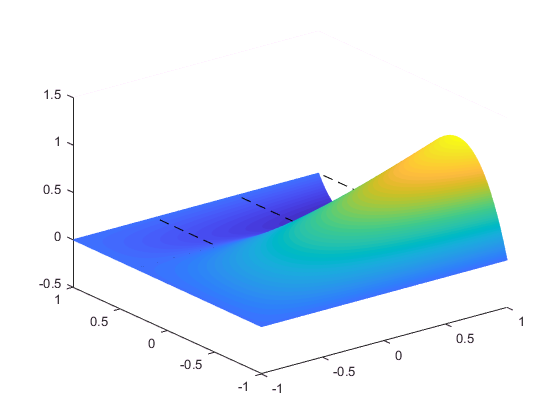


figure;
plot_grid(nodes);
plot_shape(create_shape_function(linear_nodes, 2), create_shape_function(nodes, 2));